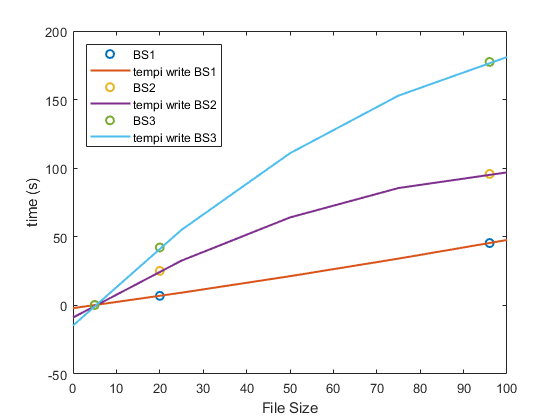

BS1 = [0.1946421, 6.9501139, 45.446537];
BS2 = [0.2502291, 25.144526, 95.802747];
BS3 = [0.3620381, 42.213661, 177.45106];

FS = [5, 20, 96];

t=linspace(0,100,5);

p1 = polyfit(FS,BS1,2);
p2 = polyfit(FS,BS2,2);
p3 = polyfit(FS,BS3,2);

y1 = polyval(p1,t);
y2 = polyval(p2,t);
y3 = polyval(p3,t);



plot(FS,BS1,'o',t,y1,'LineWidth',1.5)
hold on
plot(FS,BS2,'o',t,y2,'LineWidth',1.5)
hold on
plot(FS,BS3,'o',t,y3,'LineWidth',1.5)

xlabel('File Size')
ylabel('time (s)')

legend('BS1','tempi write BS1','BS2','tempi write BS2','BS3','tempi write BS3','Location','northwest')